syms a alpha d theta;

A = [cos(theta) -sin(theta)*cos(alpha)   sin(theta)*sin(alpha) a*cos(theta);
     sin(theta) cos(theta)*cos(alpha)   -cos(theta)*sin(alpha) a*sin(theta);
     0  sin(alpha)  cos(alpha)  d
     0  0   0   1
];


## Anthropomorphic Arm

## Compute Forward Kinematics

syms a1 alpha1 d1 theta1 a2 alpha2 d2 theta2 a3 alpha3 d3 theta3;

% DH parameters
a1 = 0; a2 = 0.5; a3 = 0.5;
alpha1 = pi/2; alpha2 = 0; alpha3 = 0;
d1 = 0.7; d2 =0; d3 = 0;

% Denavit-Hartenberg matrices
A1 = subs(A, [a alpha d theta],[a1 alpha1 d1 theta1]);
A2 = subs(A, [a alpha d theta],[a2 alpha2 d2 theta2]);
A3 = subs(A, [a alpha d theta],[a3 alpha3 d3 theta3]);

% Compute cumulative transformations
T00 = eye(4);
T01 = A1;
T02 = simplify(A1 * A2);
T03 = simplify(A1*A2*A3); % Base to end-effector


## Compute Jacobian

Jv = simplify([cross(T00(1:3,3),T03(1:3,4)-T00(1:3,4))   cross(T01(1:3,3),T03(1:3,4)-T01(1:3,4))  cross(T02(1:3,3),T03(1:3,4)-T02(1:3,4))]);
Jw = simplify([T00(1:3,3)    T01(1:3,3)  T02(1:3,3)]);

J = [Jv; Jw];

% Display the Geometric Jacobian J
disp('The Geometric Jacobian is:');

The Geometric Jacobian is:


disp(J);

$$\begin{array}{l} \left(\begin{array}{ccc} -\frac{\sin\left(\theta_{1}\right)\,\sigma_{2}}{2} & -\cos\left(\theta_{1}\right)\,\sigma_{1} & -\frac{\sin\left(\theta_{2}+\theta_{3}\right)\,\cos\left(\theta_{1}\right)}{2}\\ \frac{\cos\left(\theta_{1}\right)\,\sigma_{2}}{2} & -\sin\left(\theta_{1}\right)\,\sigma_{1} & -\frac{\sin\left(\theta_{2}+\theta_{3}\right)\,\sin\left(\theta_{1}\right)}{2}\\ 0 & \sigma_{3}+\frac{\cos\left(\theta_{2}\right)}{2} & \sigma_{3}\\ 0 & \sin\left(\theta_{1}\right) & \sin\left(\theta_{1}\right)\\ 0 & -\cos\left(\theta_{1}\right) & -\cos\left(\theta_{1}\right)\\ 1 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sin\left(\theta_{2}+\theta_{3}\right)}{2}+\frac{\sin\left(\theta_{2}\right)}{2}\\ \sigma_{2}=\cos\left(\theta_{2}+\theta_{3}\right)+\cos\left(\theta_{2}\right)\\ \sigma_{3}=\frac{\cos\left(\theta_{2}+\theta_{3}\right)}{2} \end{array}$$


% Display the reduced Geometric Jacobian J
disp('The reduced Geometric Jacobian (with Linearly independent rows) is:');

The reduced Geometric Jacobian (with Linearly independent rows) is:


disp(Jv);

$$\begin{array}{l} \left(\begin{array}{ccc} -\frac{\sin\left(\theta_{1}\right)\,\sigma_{2}}{2} & -\cos\left(\theta_{1}\right)\,\sigma_{1} & -\frac{\sin\left(\theta_{2}+\theta_{3}\right)\,\cos\left(\theta_{1}\right)}{2}\\ \frac{\cos\left(\theta_{1}\right)\,\sigma_{2}}{2} & -\sin\left(\theta_{1}\right)\,\sigma_{1} & -\frac{\sin\left(\theta_{2}+\theta_{3}\right)\,\sin\left(\theta_{1}\right)}{2}\\ 0 & \frac{\cos\left(\theta_{2}+\theta_{3}\right)}{2}+\frac{\cos\left(\theta_{2}\right)}{2} & \frac{\cos\left(\theta_{2}+\theta_{3}\right)}{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sin\left(\theta_{2}+\theta_{3}\right)}{2}+\frac{\sin\left(\theta_{2}\right)}{2}\\ \sigma_{2}=\cos\left(\theta_{2}+\theta_{3}\right)+\cos\left(\theta_{2}\right) \end{array}$$


% Compute the determinant
determinant = simplify(det(Jv));

% Display the equation for the determinant
disp('The determinant is:');

The determinant is:


disp(determinant);

$$-\frac{\left(\cos\left(\theta_{3}\right)+1\right)\,\left(\sin\left(\theta_{2}+\theta_{3}\right)-\sin\left(\theta_{2}\right)\right)}{8}$$


% Compute the singularities
singularities = solve(determinant == 0, theta2, theta3, 'ReturnConditions', true);

% Display the singularities 
disp('The shoulder singularities are found at theta2:');

The shoulder singularities are found at theta2:


disp(singularities.theta2);

$$\left(\begin{array}{c} z\\ \frac{\pi }{2}-\frac{z}{2}+\pi \,l\\ z \end{array}\right)$$


% Display the singularities 
disp('The boundary singularities are found at theta3:');

The boundary singularities are found at theta3:


disp(singularities.theta3);

$$\left(\begin{array}{c} \pi \,\left(2\,k+1\right)\\ z\\ 2\,\pi \,k \end{array}\right)$$



disp('For an Anthropomorphic arm, shoulder singularities can occur where the shoulder and elbow joint axes become coplanar.');

For an Anthropomorphic arm, shoulder singularities can occur where the shoulder and elbow joint axes become coplanar.


disp(' Elbow singularities can also occur where the links 1 and 2 are collinear.');

 Elbow singularities can also occur where the links 1 and 2 are collinear.


N = 100;


## Plot Surface of the Dterminant

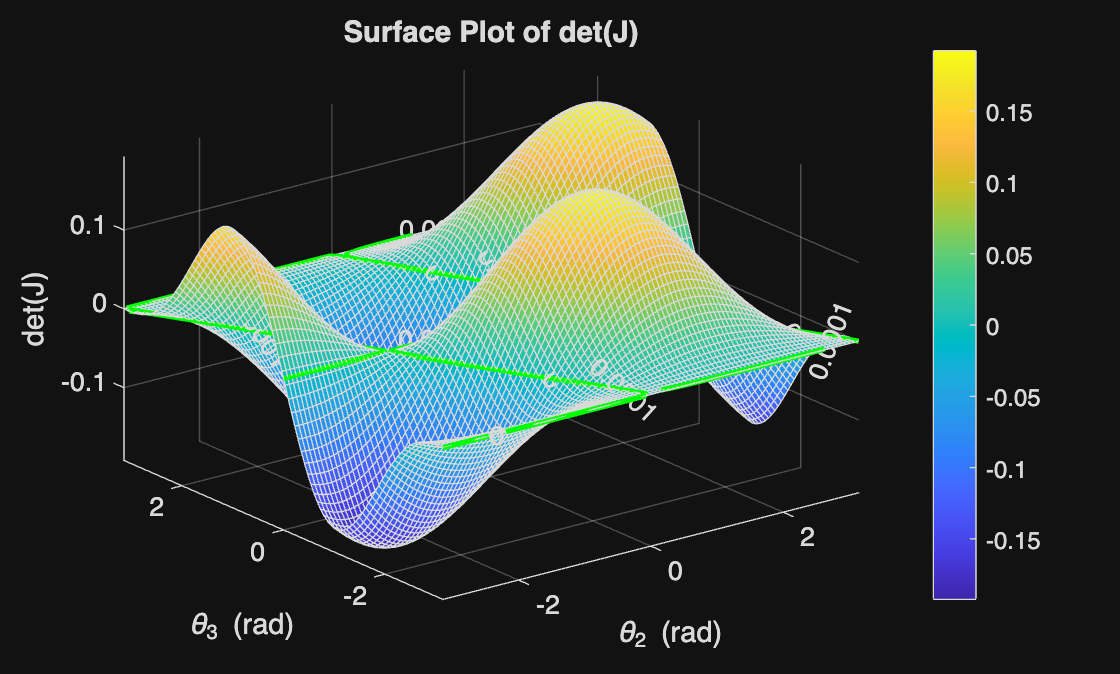


% Define values of theta 2 and theta 3 for which determinants will be calculated
theta2_vals = linspace(-pi, pi, N);
theta3_vals = linspace(-pi, pi, N);
[th2, th3] = meshgrid(theta2_vals, theta3_vals);

% Compute determinants
determinants = double(subs(determinant, {theta2, theta3}, {th2, th3}));


% Define tolerance
tolerance = 0.0001;

figure;
surf(th2, th3, determinants);
hold on;
xlabel('\theta_2 (rad)'); ylabel('\theta_3 (rad)');
zlabel('det(J)');
title('Surface Plot of det(J)');

% Contour plot highlighting det ≈ 0
contour(th2, th3, determinants, [0 tolerance], 'LineWidth', 2, 'LineColor', 'g', 'ShowText', 'on');  % zero contour
colorbar; grid on;
hold off;

## Plot Subset of Determinant Corresponding to Shoulder Singularities

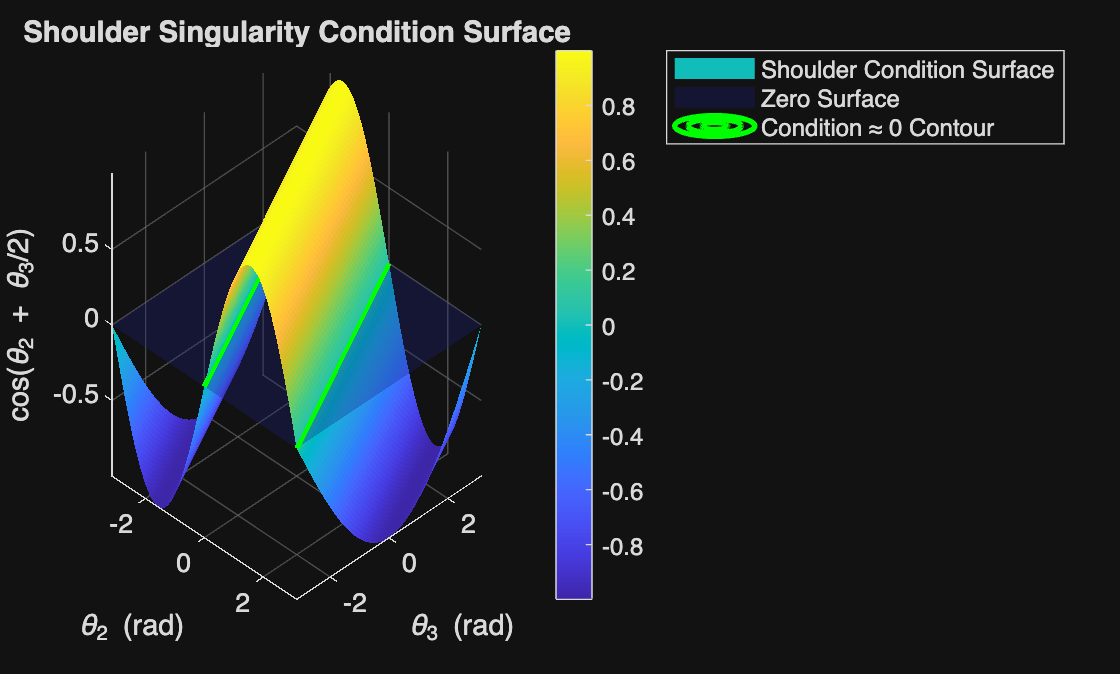

%% Shoulder Singularity Visualization
% Given: th2, th3 (from meshgrid), determinants, N, tolerance

% Step 1. Compute the shoulder singularity condition
shoulder_condition = cos(th2 + th3/2);

% Step 2. Plot the surface of the condition
figure;
surf(th2, th3, shoulder_condition, 'EdgeColor', 'none');
xlabel('\theta_2 (rad)');
ylabel('\theta_3 (rad)');
zlabel('cos(\theta_2 + \theta_3/2)');
title('Shoulder Singularity Condition Surface');
colorbar; grid on; hold on;
view(45, 30);

% Step 3. Add a zero surface (z = 0 plane)
z0 = zeros(size(th2));
surf(th2, th3, z0, 'FaceColor', [0.1 0.1 0.5], 'FaceAlpha', 0.3, 'EdgeColor', 'none');

% Step 4. Add contour lines where condition ≈ 0
contour3(th2, th3, shoulder_condition, [0 tolerance], 'LineWidth', 2, 'LineColor', 'g');


legend('Shoulder Condition Surface', 'Zero Surface', 'Condition ≈ 0 Contour');
hold off;

## Plot Joint Velocities

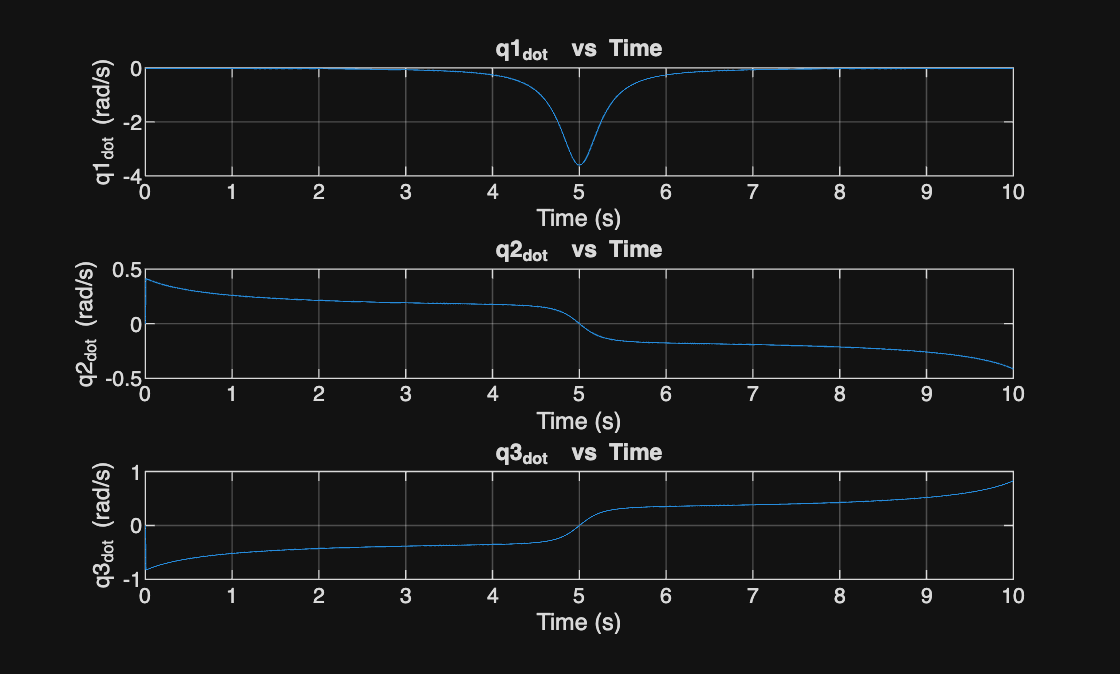

% Number of points
N = 201;

% Time vector (column)
t = linspace(0, 10, N)';  % 5 seconds simulation (adjust as needed)

%% Define start and end points for the slanted line
start_point = [-0.9, 0.05, 0.7];       % Starting point (x1, y1, z1)
end_point = [0.9, 0.05,0.7]; % Ending point (x2, y2, z2)

% Interpolate only x; y and z are constant
x = linspace(start_point(1), end_point(1), N)';  % x from 0.2 → 0.9
y = repmat(start_point(2), N, 1);               % y constant at 0.05
z = repmat(start_point(3), N, 1);               % z constant at 0.7

% --- Combine into workspace matrices for From Workspace blocks ---
X_block_data = [t, x];   % 201 x 2
Y_block_data = [t, y];   % 201 x 2
Z_block_data = [t, z];   % 201 x 2

% Spline points for Mechanical Explorer for Straight line
% Spline expects N x 3 matrix: [x, y, z]
SplinePoints = [x, y, z];    % 201 x 3


% Plot joint velocities with time

subplot(3, 1, 1);
plot(out.q1_dot.Time, out.q1_dot.Data);
xlabel('Time (s)');
ylabel('q1_d_o_t (rad/s)');
title('q1_d_o_t  vs Time');
grid on;

subplot(3, 1, 2);
plot(out.q2_dot.Time, out.q2_dot.Data);
xlabel('Time (s)');
ylabel('q2_d_o_t (rad/s)');
title('q2_d_o_t  vs Time');
grid on;

subplot(3, 1, 3);
plot(out.q3_dot.Time, out.q3_dot.Data);
xlabel('Time (s)');
ylabel('q3_d_o_t (rad/s)');
title('q3_d_o_t  vs Time');
grid on;


%% Study effect of singularity proximity on joint 2 angular velocity

% Simulation settings
model = 'Anthropomorphic_Arm_Robot';    % <-- change to your model name
offsets = linspace(-0.1, 0.1, 21);   % Path offset (m)

%% Define start and end points for the slanted line
start_point = [-0.9, 0.0, 0.7];       % Starting point (x1, y1, z1)
end_point = [0.9, 0.0,0.7]; % Ending point (x2, y2, z2)

x = linspace(start_point(1), end_point(1), N)';
z = repmat(start_point(3), N, 1);

% Preallocate
all_q1dot = [];
all_time = [];
all_offset = [];

for k = 1:length(offsets)
    offset = offsets(k);
    fprintf('Running simulation %d of %d: offset = %.3f m\n', k, length(offsets), offset);

    % Shift path
    y = repmat(start_point(2) + offset, N, 1);
    X_block_data = [t, x];
    Y_block_data = [t, y];
    Z_block_data = [t, z];
    SplinePoints = [x, y, z];

    % Run model
    simOut = sim(model, 'StopTime', '10');

    % Extract time and q2_dot
    time = simOut.q1_dot.Time;
    q1dot = simOut.q1_dot.Data;

    % Downsample both to same fixed length
    q1dot_ds = q1dot(1:100:end);
    time_ds = time(1:100:end);

    % --- First run: initialize matrix with correct width ---
    if k == 1
        all_time = time_ds';
        all_q1dot = zeros(length(offsets), length(time_ds));
    end

    % --- If current run shorter, pad with NaN ---
    if length(q1dot_ds) < size(all_q1dot, 2)
        q1dot_ds(end+1:size(all_q1dot,2)) = NaN;
    elseif length(q1dot_ds) > size(all_q1dot, 2)
        q1dot_ds = q1dot_ds(1:size(all_q1dot,2));
    end

    % Store this run as a row
    all_q1dot(k, :) = q1dot_ds';
end

Running simulation 1 of 21: offset = -0.100 m


Running simulation 2 of 21: offset = -0.090 m


Running simulation 3 of 21: offset = -0.080 m


Running simulation 4 of 21: offset = -0.070 m


Running simulation 5 of 21: offset = -0.060 m


Running simulation 6 of 21: offset = -0.050 m


Running simulation 7 of 21: offset = -0.040 m


Running simulation 8 of 21: offset = -0.030 m


Running simulation 9 of 21: offset = -0.020 m


Running simulation 10 of 21: offset = -0.010 m


Running simulation 11 of 21: offset = 0.000 m


Running simulation 12 of 21: offset = 0.010 m


Running simulation 13 of 21: offset = 0.020 m


Running simulation 14 of 21: offset = 0.030 m


Running simulation 15 of 21: offset = 0.040 m


Running simulation 16 of 21: offset = 0.050 m


Running simulation 17 of 21: offset = 0.060 m


Running simulation 18 of 21: offset = 0.070 m


Running simulation 19 of 21: offset = 0.080 m


Running simulation 20 of 21: offset = 0.090 m


Running simulation 21 of 21: offset = 0.100 m


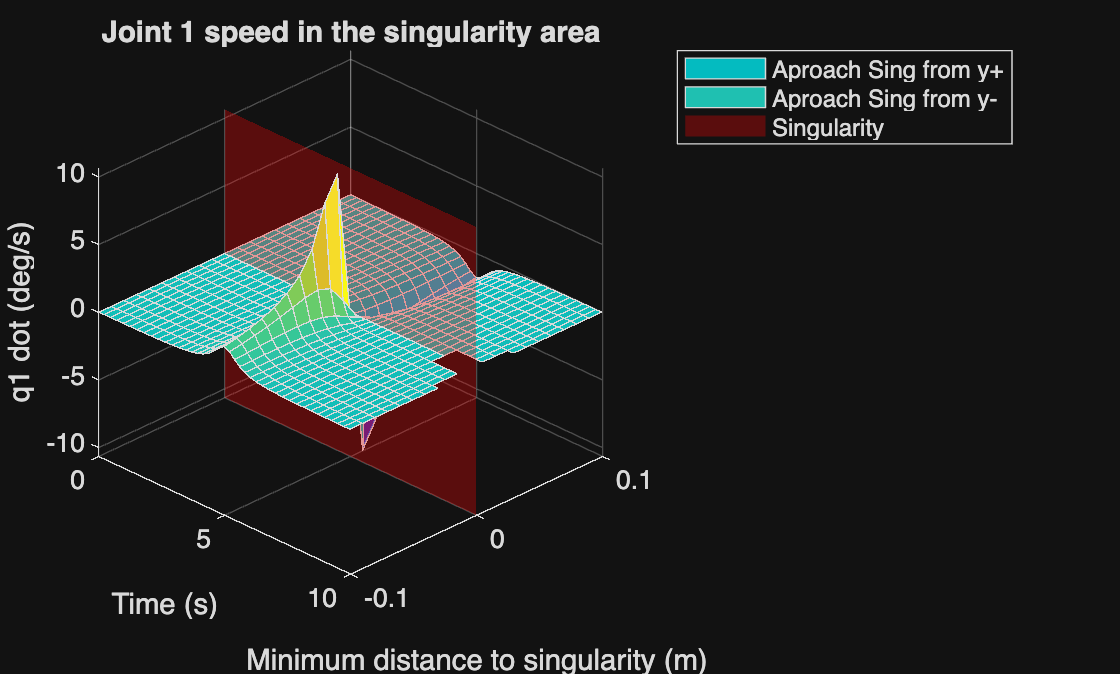


% Convert to matrix form for surface plot
[T, Y] = meshgrid(all_time, offsets);
Z = all_q1dot;

% Separate positive and negative offsets
Z_pos = Z;  Z_pos(offsets < 0, :) = NaN;
Z_neg = Z;  Z_neg(offsets > 0, :) = NaN;

% Plot surfaces
% --- Plot the two approach surfaces ---
figure;
surf(T, Y, Z_pos);   % +y approach
hold on;
surf(T, Y, Z_neg);  % -y approach (teal-like color)

% --- Create the red singularity plane (rectangular and vertical) ---
tmin = min(all_time);
tmax = max(all_time);
zmin = min(Z(:), [], 'omitnan');
zmax = max(Z(:), [], 'omitnan');

Xplane = [tmin, tmax; tmin, tmax];    % time dimension
Yplane = zeros(2, 2);                 % y = 0
Zplane = [zmin, zmin; zmax, zmax];    % span full vertical range

surf(Xplane, Yplane, Zplane, ...
    'FaceColor', 'red', ...           % red plane
    'FaceAlpha', 0.3, ...             % translucent
    'EdgeColor', 'none');

% Labeling and formatting
xlabel('Time (s)');
ylabel('Minimum distance to singularity (m)');
zlabel('q1 dot (deg/s)');
title('Joint 1 speed in the singularity area');

legend({'Aproach Sing from y+', 'Aproach Sing from y-', 'Singularity'}, ...
       'Location', 'northeastoutside');

grid on;
view(45, 30);
hold off;

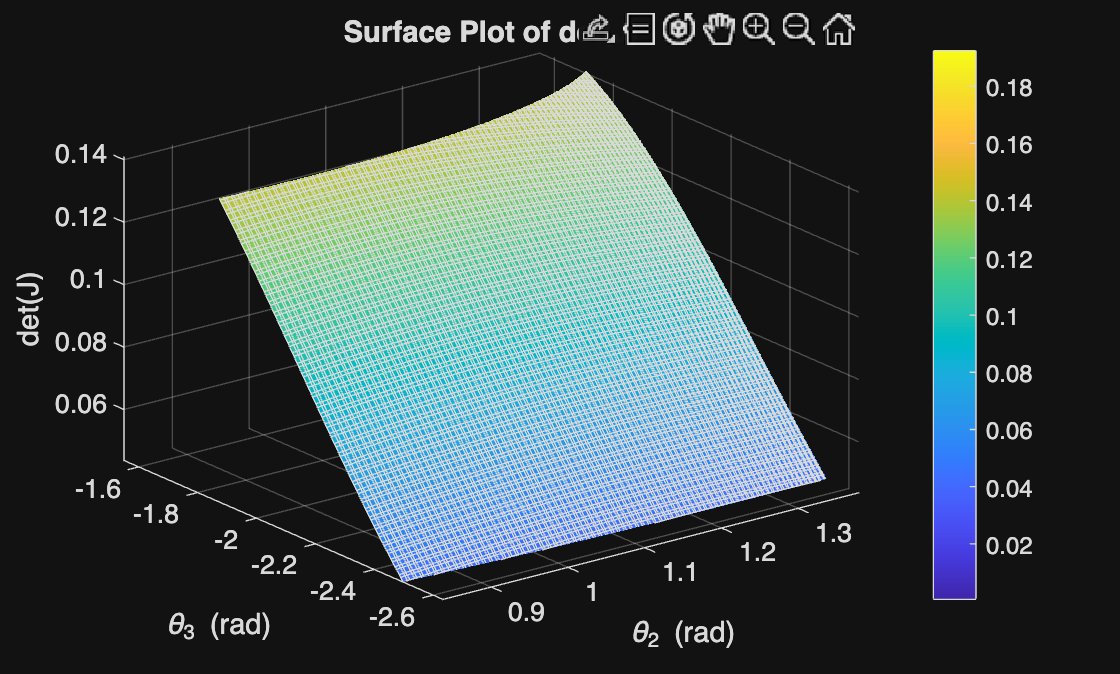



% Plot q2 and q3 values obtained from joint measurments

% Define values of theta 2 and theta 3 for which determinants will be calculated
N = 300;  % target number of samples

theta2_vals = out.q2.Data;
theta3_vals = out.q3.Data;

% Downsample uniformly
theta2_vals_ds = theta2_vals(round(linspace(1, length(theta2_vals), N)));
theta3_vals_ds = theta3_vals(round(linspace(1, length(theta3_vals), N)));

% Create meshgrid with reduced samples
[th2, th3] = meshgrid(theta2_vals_ds, theta3_vals_ds);
% Compute determinants
determinants = double(subs(determinant, {theta2, theta3}, {th2, th3}));


% Define tolerance
tolerance = 0.0001;

figure;
surf(th2, th3, determinants);
hold on;
xlabel('\theta_2 (rad)'); ylabel('\theta_3 (rad)');
zlabel('det(J)');
title('Surface Plot of det(J)');

% Contour plot highlighting det ≈ 0
contour(th2, th3, determinants, [0 tolerance], 'LineWidth', 2, 'LineColor', 'g', 'ShowText', 'on');  % zero contour
colorbar; grid on;
hold off;